# Lab 4

Importing data...

h5disp("gammaray_lab4.h5");

HDF5 gammaray_lab4.h5 
Group '/' 
    Dataset 'data' 
        Size:  25920001x4
        MaxSize:  25920001x4
        Datatype:   H5T_IEEE_F64LE (double)
        ChunkSize:  []
        Filters:  none
        FillValue:  0.000000


mydata = h5read("gammaray_lab4.h5",'/data');
mydata(1,:);

## Problem 1

In this problem we are looking at the data from a gamma-ray satellite orbiting in low Earth orbit. It takes a reading of the number of particles detected every 100 milliseconds, and is in an approximately 90 minute orbit. While it is looking for gamma-ray bursts, virtually all of the particles detected are background cosmic rays.

As with most data, there are 'features.' Your lab instructor has helpfully incorporated the meta-data into your data file.

1) Down load the data from the course website (gammaray_lab4.h5), and import it into your working environment. The data has 4 columns and more than 25 million rows. The columns are time (in gps seconds), Solar phase (deg) showing the position of the sun relative to the orbit, Earth longitude (deg) giving the position of the spacecraft relative to the ground, and particle counts. Make a few plots, generally exploring your data and making sure you understand it. Give a high level description of the data features you see. Specifically comment on whether you see signal contamination in your data, and how you plan to build a background pdf().

Columns = time, solar phase, earth longitude, counts

see how counts are changing with each variable

time = mydata(:,1);
solphase = mydata(:,2);
earthlong = mydata(:,3);
counts = mydata(:,4);

Some basic plots versus time

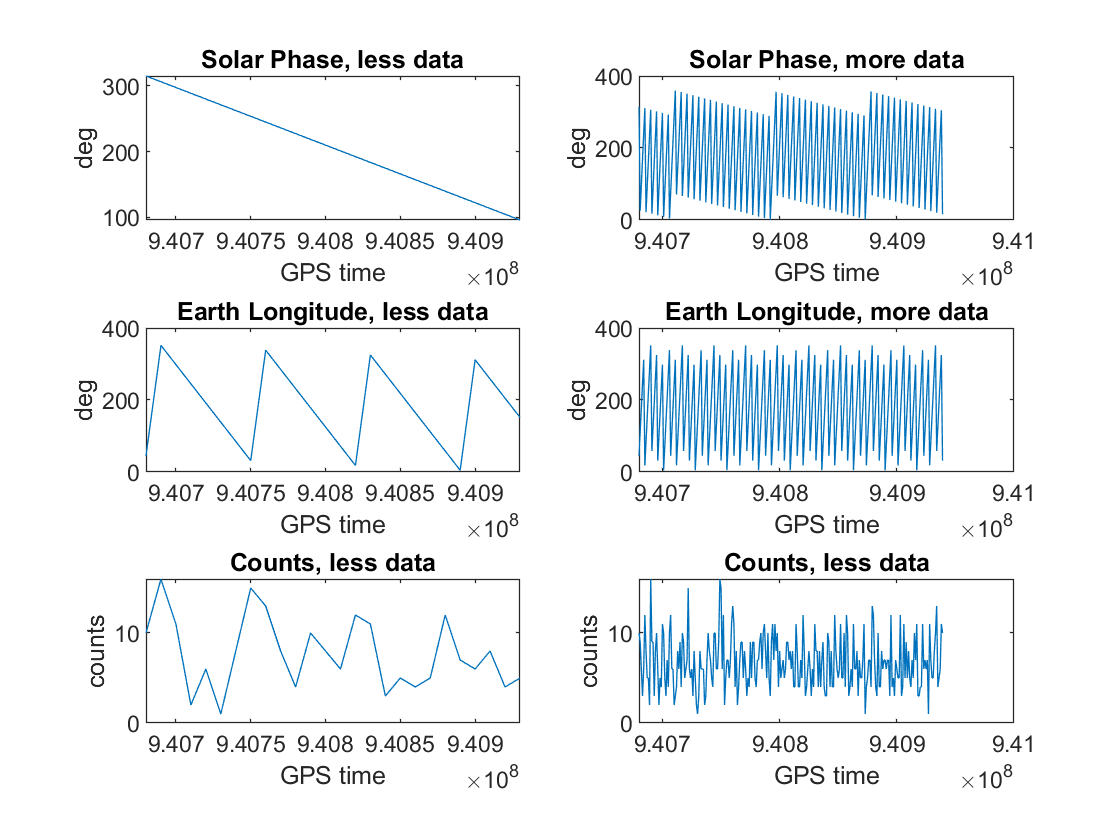

smallsp = (1:100000:2592001);
widesp = (1:10000:2592001);
subplot(3,2,1)
plot(time(smallsp),solphase(smallsp))
title('Solar Phase, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,2)
plot(time(widesp),solphase(widesp))
title('Solar Phase, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,3)
plot(time(smallsp),earthlong(smallsp))
title('Earth Longitude, less data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,4)
plot(time(widesp),earthlong(widesp))
title('Earth Longitude, more data')
xlabel('GPS time')
ylabel('deg')
subplot(3,2,5)
plot(time(smallsp),counts(smallsp))
title('Counts, less data')
xlabel('GPS time')
ylabel('counts')
subplot(3,2,6)
plot(time(widesp),counts(widesp))
title('Counts, less data')
xlabel('GPS time')
ylabel('counts')

now for a counts versus other stuff histogram portion of this lab

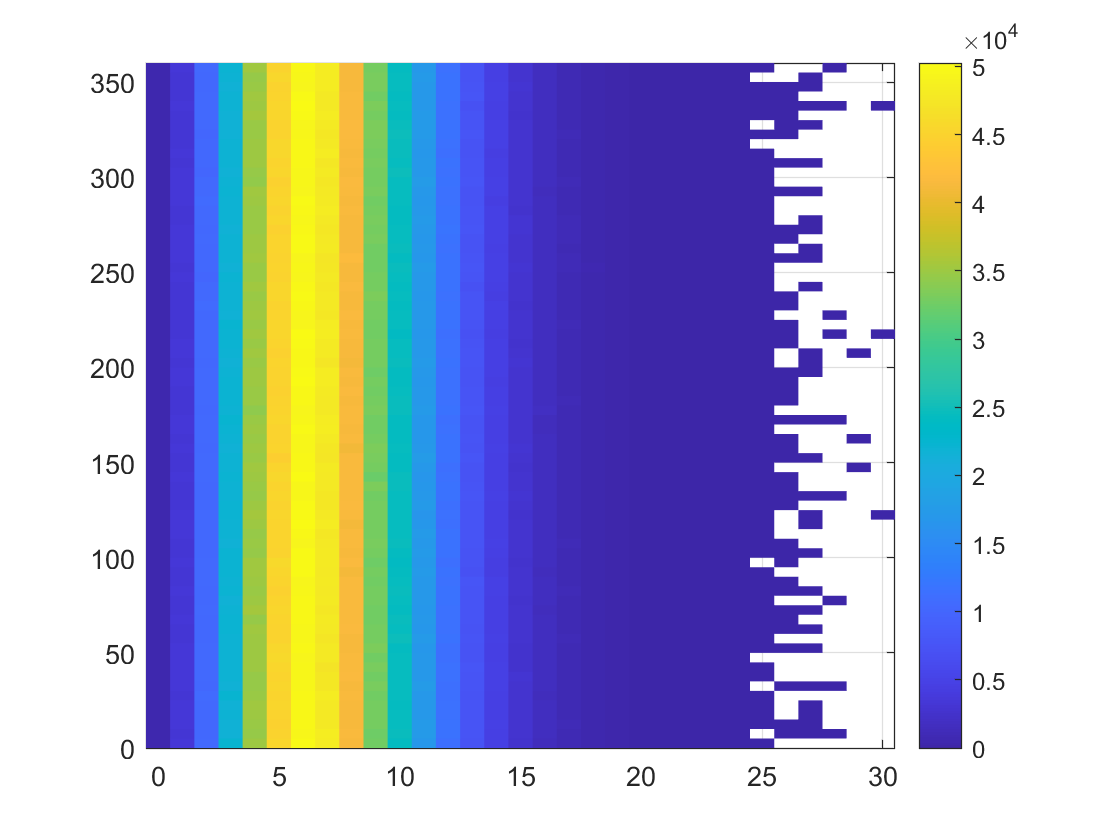

subplot(1,1,1)
histogram2(counts,solphase,'DisplayStyle','tile')
colorbar

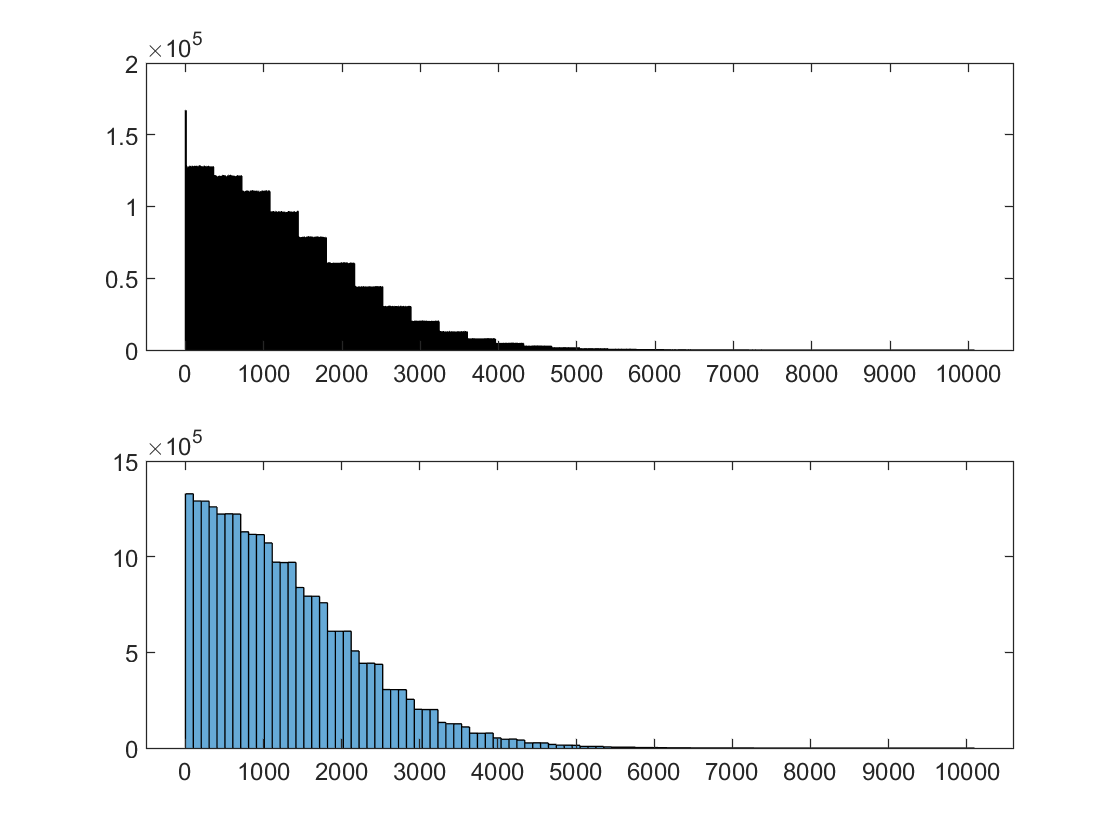


subplot(2,1,1)
histogram(solphase.*counts)
subplot(2,1,2)
histogram(solphase.*counts,100)

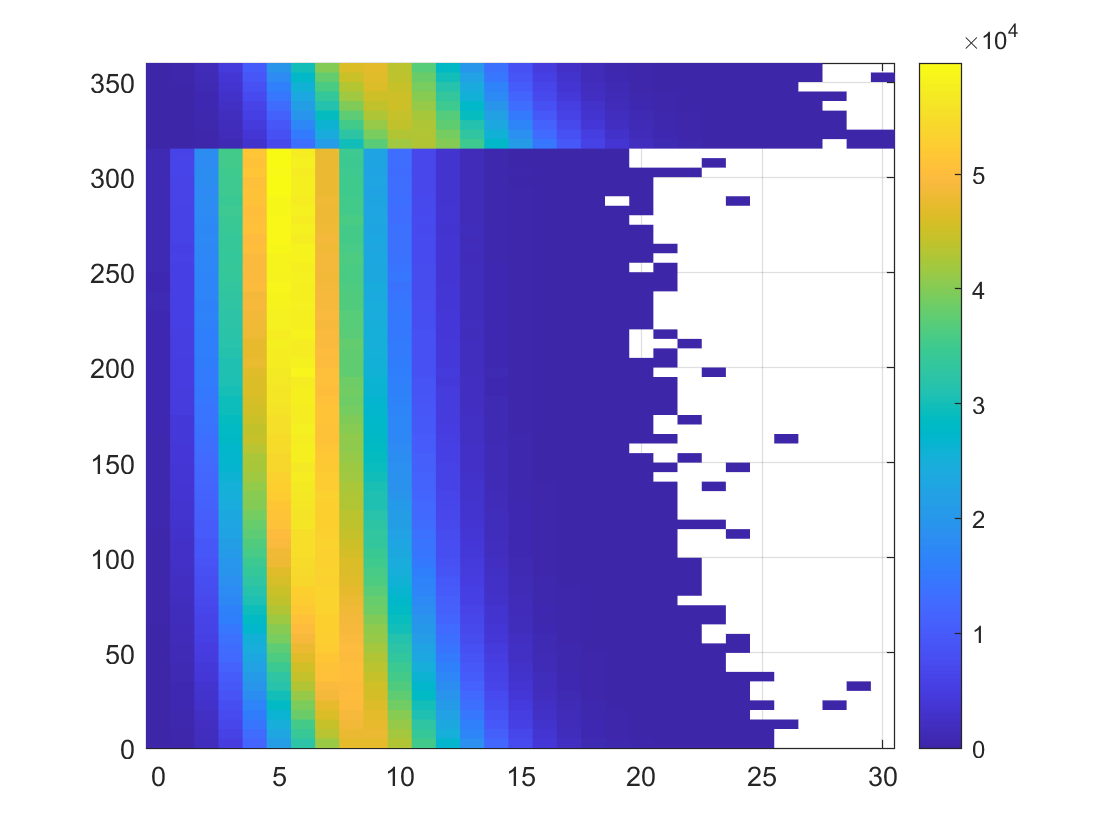

subplot(1,1,1)
histogram2(counts,earthlong,'DisplayStyle','tile')
colorbar

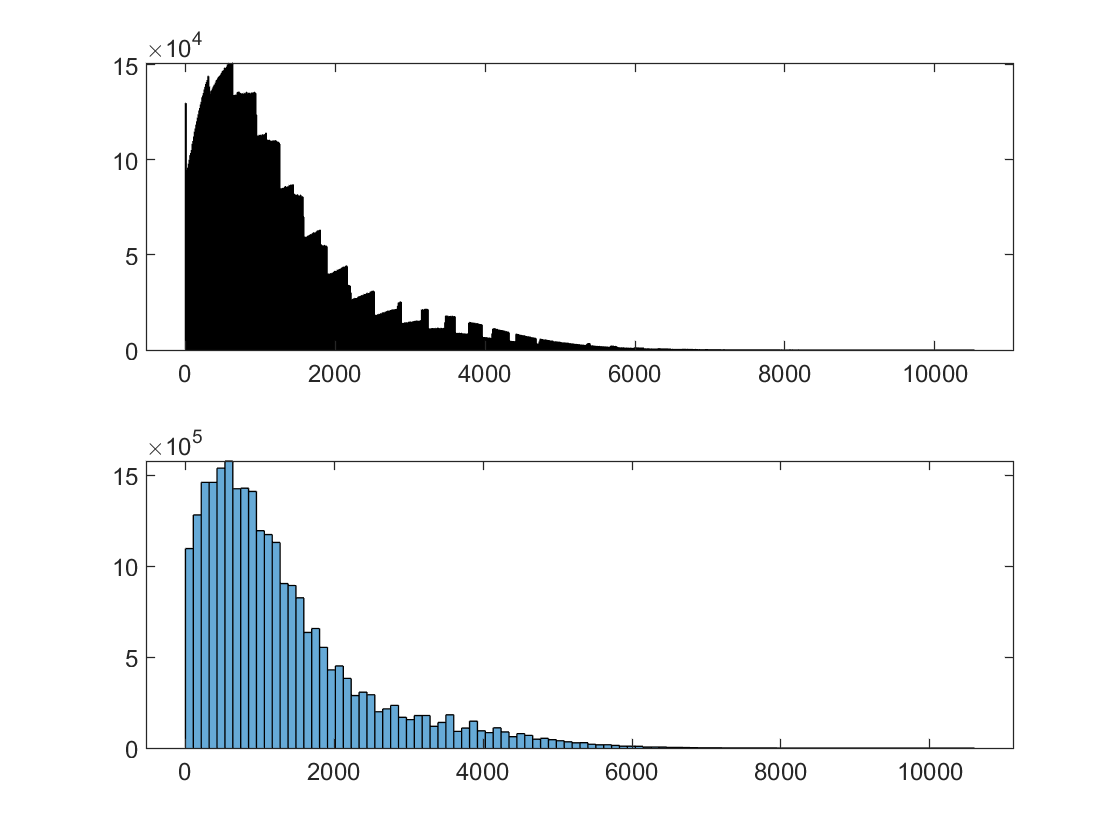

subplot(2,1,1)
histogram(earthlong.*counts)
subplot(2,1,2)
histogram(earthlong.*counts,100)

2) The background is **not** consistent across the dataset. Find and describe as accurately as you can how the background changes.

3) Create a model for the background that includes time dependence, and explicitly compare your model to the data. How good is your model of the background?

4) Because the background varies, your discovery sensitivity threshold (how many particles you would need to see) also varies. What is the '5-sigma' threshold for a 100 millisecond GRB at different times?

Optional: while this is simulated data, it is based on a real effect seen by low Earth orbit satellites. Can you identify the cause of the variable background and propose a physical model?

## Problem 2

In this problem we are going to look at a stack of telescope images (again simulated). We have 10 images, but you and your lab partner will be looking for different signals. One of you will be looking for the faintest stars, while the other will be looking for a transient (something like a super novae that only appears in one image). Flip a coin to determine which of you is pursuing which question.

1) Dowload the data from `images.h5`. This is a stack of 10 square images, each 200 pixels on a side.

2) Explore the data. Is there signal contamination? Is the background time dependent? Is it consistent spatially? Develop a plan to calculate your background pdf().

3) Using your background distribution, hunt for your signal (either faint stars, or a transient). Describe what you find.

4) You and your lab partner had different pdf(), but were using the *same* data. Explore why this is.